Mp = 0.024;
Mr = 0.095;
b1 = 0.0005;
b2 = 0.0001;
Lp = 0.129;
Lr = 0.085;
g = 9.81;
Km = 0.042;
Rm = 8.4;
Jp = Mp*Lp^2/3;
Jr = Mr*Lr^2/3;
l = Lp/2;
J0 = 5.7198e-5+Mp*Lr^2;
J2 = 3.3185e-5+Mp*(Lp/2)^2;
Jt = J0*J2-(Mp^2)*(Lr^2)*((Lp/2)^2);

a32 = g*(Mp^2)*(Lp^2)*Lr/(4*Jt);
a33 = -(b1*J2/Jt + (Km^2)*J2/(Jt*Rm));
a34 = -b2*Mp*Lp*Lr/(2*Jt);
a42 = g*Mp*Lp*J0/Jt;
a43 = -(b1*Mp*Lp*Lr/(2*Jt) + Km^2*Mp*Lp*Lr/(2*Jt*Rm));
a44 = -b2*J0/Jt;

A  = [
    0, 0, 1, 0;
    0, 0, 0, 1;
    0, a32, a33, a34;
    0, a42, a43, a44
];

B = [0;
    0;
    J2*Km/(Jt*Rm);
    Km*Mp*Lp*Lr/(2*Jt*Rm)
];


n = size(A,2); %number of state variables
%The controllability matrix will have as many rows as B and
%n times the number of columns in B
controllabilityMat = zeros(size(B,1), n*size(B,2)); %empty matrix

for ind=1:n
    %allocate the necessary rows and columns to accommodate A*B
    controllabilityMat(:,size(B,2)*(ind-1)+1:size(B,2)*ind) = (A^(ind-1))*B;
end

rrC = rank(controllabilityMat);%row rank of controllability mat
numRows = size(controllabilityMat, 1); %number of rows

disp(controllabilityMat)

   1.0e+05 *

         0    0.0005   -0.0040    0.1062
         0    0.0005   -0.0043    0.2935
    0.0005   -0.0040    0.1062   -1.6867
    0.0005   -0.0043    0.2935   -3.5175



if( rrC == numRows)
    disp("Controllable")
end

Controllable



C = [1 0 0 0;
     0 1 0 0];
D = [0; 0];

%The observability matrix will have as many columns as C, and
%n times as many rows as C
observabilityMat = zeros(n*size(C,1), size(C,2)); %empty matrix
for ind=1:n
    %allocate the necessary rows and columns to accommodate A*B
    observabilityMat(size(C,1)*(ind-1)+1:size(C,1)*ind,:) = C*A^(ind-1);
end

crO = rank(observabilityMat); %column rank of observability matrix
numCol = size(observabilityMat, 2); %number of columns in observability matrix

disp(observabilityMat)

   1.0e+03 *

    0.0010         0         0         0
         0    0.0010         0         0
         0         0    0.0010         0
         0         0         0    0.0010
         0    0.1495   -0.0071   -0.0010
         0    0.5241   -0.0070   -0.0017
         0   -1.5729    0.0568    0.1582
         0   -1.9497    0.0615    0.5340



if(crO == numCol)
    disp("Observable")
end

Observable


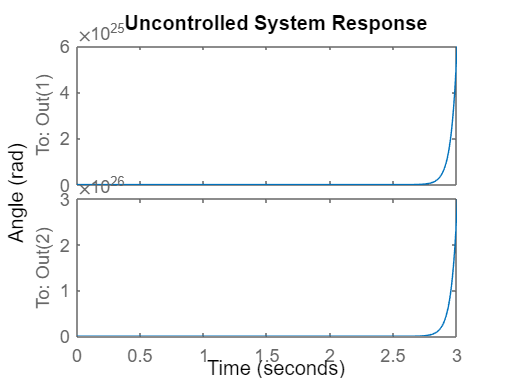


sys = ss(A, B, C, D);
pol = pole(sys);
figure()
step(sys)
ylabel("Angle (rad)")
title("Uncontrolled System Response")



p = [-25, -26, -27, -28];%desired pole placement
K = place(A, B, p)

K =   -26.2428  125.7680   -4.1627    6.1831


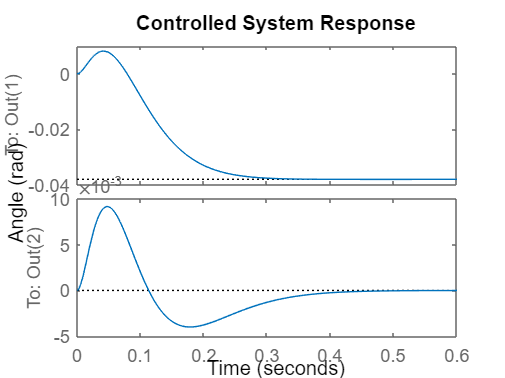

Acl = A-B*K;
syscl = ss(Acl, B, C, D);
pcl = pole(syscl);
figure()
step(syscl)
ylabel("Angle (rad)")
title("Controlled System Response")


eigs = [-500, -501, -502, -503];%desired eigenvalues
L = (place(A', C', eigs))'

L = 1.0e+05 *

    0.0100   -0.0000
   -0.0001    0.0100
    2.4434   -0.0124
   -0.0750    2.5044
